% Definição dos tamanhos das tabelas hash
hashTableSizes = [5*1e5 1e6 2*1e6];

% Número de strings a serem geradas
N = 1e5;

% Caracteres utilizados na geração das strings
chars = 'abcdefghijklmnopqrstuvwxyz';

% Probabilidades dos caracteres a partir de um arquivo 'prob_pt.txt'
prob_chars = load("prob_pt.txt");

% Limites para o tamanho das strings geradas
i_min = 6;
i_max = 20;

% Geração das strings aleatórias
strings = randStringArray(N, i_min, i_max, chars, prob_chars);

% Inicialização das estruturas para resultados
resultados = cell(4,3);
colisoes = zeros(4,3);
tempos = zeros(4,3);
codes1 = zeros(4, N);
codes2 = zeros(4, N);
codes3 = zeros(4, N);

% Loop para iterar sobre os tamanhos das tabelas hash
for i = 1:3
    fprintf("string2hash(djb2):\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para iterar sobre as strings geradas
    for j = 1:N
        code = mod(string2hash(strings{j}, 'djb2'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Atribuição dos códigos de hash às variáveis correspondentes
        if i == 1
            codes1(1, j) = code;
        elseif i == 2
            codes2(1, j) = code;
        else
            codes3(1, j) = code;
        end
    end
    resultados{1, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(1, i) = numColisoes;
    tempos(1, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(1, i));

    % Repetição similar para as outras funções de hash
    fprintf("string2hash(sdbm):\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = mod(string2hash(strings{j}, 'sdbm'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(2, j) = code;
        elseif i == 2
            codes2(2, j) = code;
        else
            codes3(2, j) = code;
        end
    end
    resultados{2, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(2, i) = numColisoes;
    tempos(2, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(2, i));

    fprintf("hashstring:\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = hashstring(strings{j}, hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(3, j) = code;
        elseif i == 2
            codes2(3, j) = code;
        else
            codes3(3, j) = code;
        end
    end
    resultados{3, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(3, i) = numColisoes;
    tempos(3, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(3, i));

    fprintf("DJB31MA:\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = mod(DJB31MA(strings{j}, 13), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(4, j) = code;
        elseif i == 2
            codes2(4, j) = code;
        else
            codes3(4, j) = code;
        end
    end
    resultados{4, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(4, i) = numColisoes;
    tempos(4, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(4, i));
    fprintf("\n\n");
end

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 500000: 17995


	Elapsed time: 0.179093



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 500000: 18211


	Elapsed time: 0.309920



hashstring:


	Número de colisões para Hash Table de tamanho 500000: 35769


	Elapsed time: 1.266159



DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 18020


	Elapsed time: 0.140650



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 1000000: 9322


	Elapsed time: 0.168675



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 1000000: 9486


	Elapsed time: 0.267316



hashstring:


	Número de colisões para Hash Table de tamanho 1000000: 29238


	Elapsed time: 1.158951



DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9521


	Elapsed time: 0.144181



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 2000000: 4648


	Elapsed time: 0.303629



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 2000000: 4939


	Elapsed time: 0.364287



hashstring:


	Número de colisões para Hash Table de tamanho 2000000: 22830


	Elapsed time: 1.176557



DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 4908


	Elapsed time: 0.132414



Momentos:


	Momento de ordem 2: 2.395000e-01
	Momento de ordem 5: 9.879800e-01
	Momento de ordem 10: 1.369859e+02


Número de colisões: 17995


Numero máximo de atribuiçoes numa posição: 5


Tempo de execução: 0.179093

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.400520e-01
	Momento de ordem 5: 1.009040e+00
	Momento de ordem 10: 1.638171e+02


Número de colisões: 18211


Numero máximo de atribuiçoes numa posição: 5


Tempo de execução: 0.309920

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.394000e-01
	Momento de ordem 5: 1.323998e+01
	Momento de ordem 10: 8.655023e+04


Número de colisões: 35769


Numero máximo de atribuiçoes numa posição: 9


Tempo de execução: 1.266159

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.396960e-01
	Momento de ordem 5: 1.006760e+00
	Momento de ordem 10: 1.676930e+02


Número de colisões: 18020


Numero máximo de atribuiçoes numa posição: 5


Tempo de execução: 0.140650

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.742550e-02
	Momento de ordem 5: 8.321562e-03
	Momento de ordem 10: 1.535270e-02


Número de colisões: 9322


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.168675

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.748250e-02
	Momento de ordem 5: 8.555937e-03
	Momento de ordem 10: 1.837718e-02


Número de colisões: 9486


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.267316

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.944200e-02
	Momento de ordem 5: 1.687428e-01
	Momento de ordem 10: 3.237745e+01


Número de colisões: 29238


Numero máximo de atribuiçoes numa posição: 9


Tempo de execução: 1.158951

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.750350e-02
	Momento de ordem 5: 8.658125e-03
	Momento de ordem 10: 1.843978e-02


Número de colisões: 9521


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.144181

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.818444e-03
	Momento de ordem 5: 3.604527e-04
	Momento de ordem 10: 3.459408e-05


Número de colisões: 4648


Numero máximo de atribuiçoes numa posição: 3


Tempo de execução: 0.303629

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.835111e-03
	Momento de ordem 5: 3.706379e-04
	Momento de ordem 10: 3.731420e-05


Número de colisões: 4939


Numero máximo de atribuiçoes numa posição: 3


Tempo de execução: 0.364287

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 7.857667e-03
	Momento de ordem 5: 6.616872e-03
	Momento de ordem 10: 1.226462e-01


Número de colisões: 22830


Numero máximo de atribuiçoes numa posição: 8


Tempo de execução: 1.176557

------------------------------------------------------------------------------------------


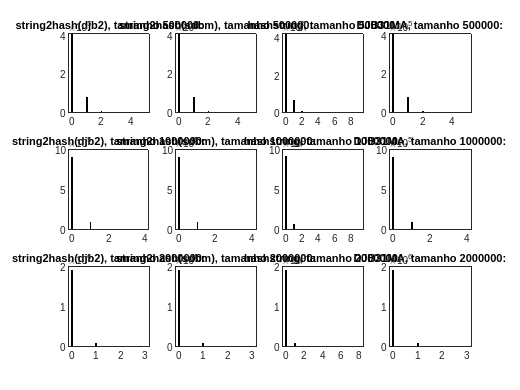

Momentos:


	Momento de ordem 2: 5.834556e-03
	Momento de ordem 5: 3.724897e-04
	Momento de ordem 10: 4.058902e-05


Número de colisões: 4908


Numero máximo de atribuiçoes numa posição: 3


Tempo de execução: 0.132414

------------------------------------------------------------------------------------------



% Configuração dos títulos para os histogramas
titles = {'string2hash(djb2)', 'string2hash(sdbm)', 'hashstring', 'DJB31MA'};
momentos = zeros(3, 10);

% Loop para plotar histogramas e calcular momentos
for i = 1:3
    for j = 1:4
        subplot(3, 4, 4 * (i - 1) + j);
        histogram(resultados{j, i}, 100);
        title(sprintf("%s, tamanho %d:", titles{j}, hashTableSizes(i)));

        fprintf("Momentos:\n");
        valores = resultados{j, i} / i;
        [contagem, valores] = groupcounts(valores);
        for n = [2, 5, 10]       
            En = 0;
            for x = 1:length(valores)
                En = En + ((valores(x)^n) * (contagem(x) / hashTableSizes(i)));
            end
            momentos(i, n) = En;
            fprintf("\tMomento de ordem %d: %d\n", n, En);
        end

        fprintf("\n");
        fprintf("Número de colisões: %d\n", colisoes(j, i));
        fprintf("Numero máximo de atribuiçoes numa posição: %d\n", max(resultados{j, i}));
        fprintf("Tempo de execução: %f", tempos(j, i));
        fprintf("\n");
        fprintf("------------------------------------------------------------------------------------------\n")
    end
end